# Radial coordinates - Polar recharge

clear
set_demo_defaults;
R_mars = 3389508;    % [m] Mars' mean radius 
grav = 3.711;   % [m/s^2] grav. acceleration on Mars

To be able to account properly for the polar recharge discussed by Clifford (1993) we need to consider cylindrical geometry of the aquifer near the pole. In linear geometry, considered so far, the polar basal melting rates are meaningless because the width of the linear aquifer considered so far is arbitrary.

In the images of Mars south polar region below the radial geometry is nicely illustrated by the graticule, i.e., the grid formed by the lines of latitude and longitude.

**Ice surface topography                      Bedrock topography**

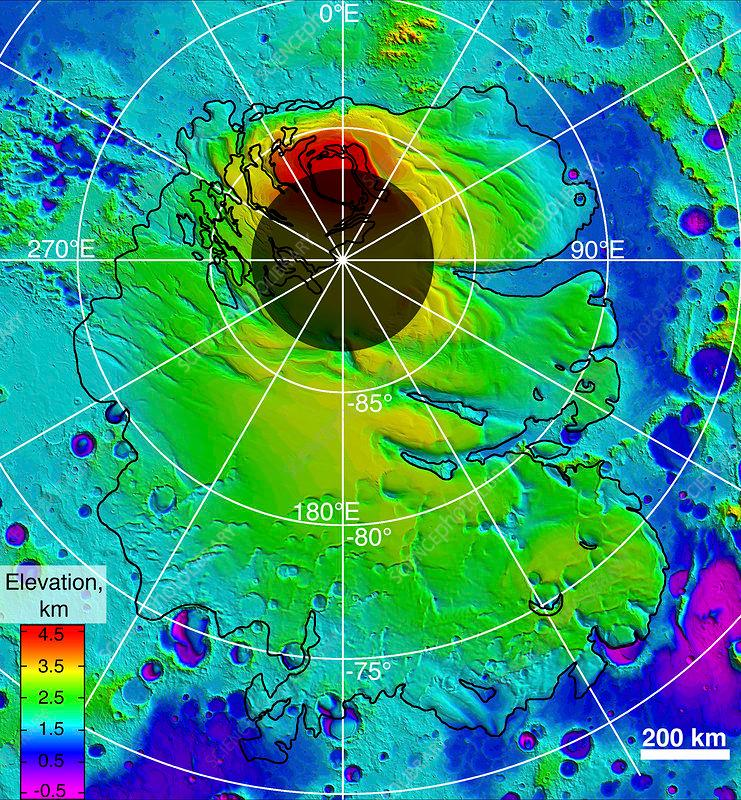  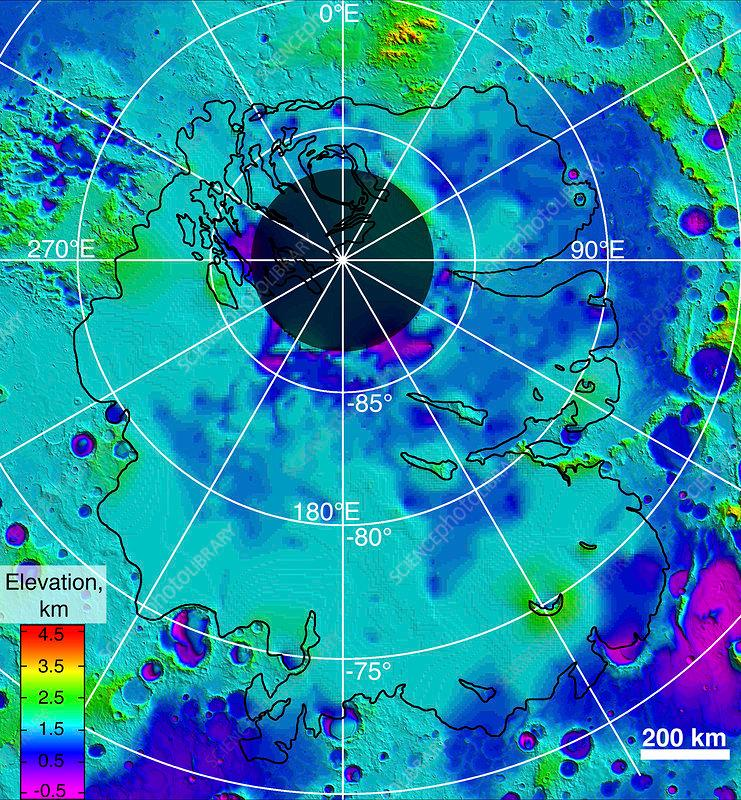

The southern polar region of Mars consists of an ice cap (black boundary) of layered ice deposits. It reaches a thickness of more than 3.7 kilometres and is mostly water ice. Image data collected between 1997 and 2001 by the Mars Orbiter Laser Altimeter (MOLA) aboard NASA's Mars Global Surveyor orbiter.

Below we will impose the polar recharge at the average lattitude of the south polar cap of approximately $\theta=-90\deg$, which corresponds to a radial distance from the south pole of

theta_pole = deg2rad(10);
rp = R_mars*theta_pole  % [m] distance from pole

rp = 5.9158e+05

The distance to the dichotomy boundary is 

theta_bnd = acos(1/3);
l = R_mars*(pi-theta_bnd) % [m] distance to dichotomy bnd

l = 6.4761e+06

as before.

## Operators in cylindrical coordinates

### Cylindrical coordinates

The advantage of the dyadic notation ($\nabla$, $\nabla \cdot$,$\nabla \times$) is that it hides the coordinate system. Here we show that the same can be achived by the discrete operators `D` and `G`. The definition of standard variable in cylindrical coordinates is shown in the figure below.

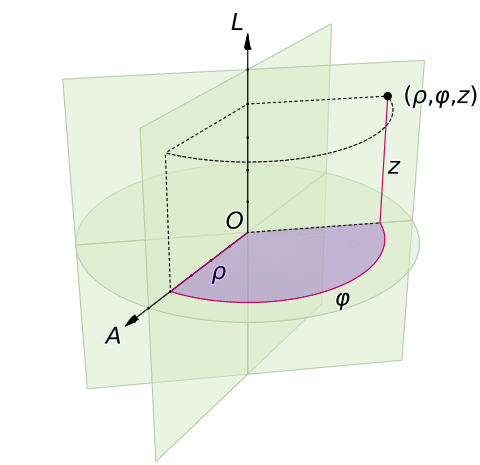

Here $\rho = r$ is the radial coordinate and $\varphi$ is the circumferecial coordinate. The associated definition of the gradient and the divergence 

- 
$$\nabla h = \frac{\partial h}{\partial \rho} \hat{\mathbf{\rho}} + \frac{1}{\rho}\frac{\partial h}{\partial\varphi} \hat{\mathbf{\varphi}} +  \frac{\partial h}{\partial z} \hat{\mathbf{z}}$$


- 
$$\nabla\cdot\mathbf{q} = \frac{1}{\rho} \frac{\partial(\rho q_\rho)}{\partial}+ \frac{1}{\rho} \frac{\partial q_\varphi}{\partial\varphi}+  \frac{\partial q_z}{\partial z}$$


where $\mathbf{q} = [q_\rho \, q_\varphi\, q_z]$.

For the one-dimensional model we only need the the $\rho$ direction and assume that there is no change in $\varphi$ and $z$. In the one dimensional cylindrical geometry, $x=r$, we have the operators

- *gradient*: $\nabla = \frac{\mathrm{d}}{\mathrm{d}x}$

- *divergence*: $\nabla\cdot =\frac{1}{x} \frac{\mathrm{d}}{\mathrm{d}x}x $

The gradient is the same as in linear coordinates, but the divergence changes. So we have to update the function build_ops.m to account for cylindrical geometry.

### Geometric interpretation of the radius terms

The key to the correct discretization is the geometric understanding of the two radius terms in the divergence. To facilitate this consider the equation for the steady state temperature with a heat source

in compact dyadic notation$-\nabla\cdot\left[K\nabla h\right] = f_s$  

or written explicitly in terms of the radial coordinate  $-\frac{\mathrm{d}}{\mathrm{d}x}\left[x\,K \frac{\mathrm{d}h}{\mathrm{d}x}\right] = x\,f_s$.

Note, here we have multiplied through by $x$, so that it is on the right hand side. In this form, the geometric origin of the two radius terms becomes clearer.

- The term $x\,K$ suggests that this $x$ represents that growth of the interfacial area with increasing radius, because $K
$ is associate with the flux. This radius term should therefore evaluated at the cell faces `Grid.xf`.

- The term $x\,f_s$ suggests that this $x$ represents the growth of the volume with increasing radius, because $f_s$ is the volumetic source term. This radius term should therefore be evaluated at the cell centers `Grid.xc`.

### Discretization of the divergence

The radial component of the discrete divergence matrix in cylindical and spherical geometry can therefore be obtained as follows:

Grid.xmin = 0.1; Grid.xmax = 1; Grid.Nx = 35;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
fs = spalloc(Grid.Nx,1,0);

% Cylindrical coordinate system (1D radial)
Rinv = spdiags(1./Grid.xc,0,Grid.Nx,Grid.Nx);
R = spdiags(Grid.xf,0,Grid.Nfx,Grid.Nfx);
D = Rinv*D*R;
L = -D*G;

Note that including the origin, $r=0$, is not a problem because the term $1/x$ is evaluated at cell centers!

## Cyindrical aquifer with polar recharge

#### Dimensional

The equations for the steady confined cylindrical aquifer with polar recharge is given by

$-\frac{1}{r}\frac{\mathrm{d} }{\mathrm{d} r}\left[b\,K\frac{\mathrm{d} h}{\mathrm{d} r}\right] = 0$ on $r \in \left[r_p,\, l\right]$

with the boundary conditions

$q_i = -K\left.\frac{\mathrm{d} h}{\mathrm{d} r}\right|_{r_p} $ and $h(l) = h_o$.

The parameter values are as before

yr2s = 60^2*24*365.25;  % second per year
rho = 1e3;              % [kg/m^3] desity of water 
grav = 3.711;           % [m/s^2] grav. acceleration on Mars
k = 1e-11;              % [m^2] permeability (Hanna & Phillips 2005)
mu = 1e-3;              % [Pa s] water viscosity
ho = -500;              % [m] sea level
b = 5e3; % [m] aquifer thickness
Qi = 1e9/yr2s           % [m^3/s] polar rechrge rate Q = 1km^3/yr from Clifford 1993

Qi = 31.6881

% derived values
K = k*rho*grav/mu;      % [m/s] hydraulic conductivity
qi = @(rp) Qi/(b*2*pi*rp); % [m/s] recharge flux 

#### Dimensionless 

Choosing the dimensionless variables $r'-r/l$ and $h'=(h-h_o)/(q_il/K)$we have the dimensionless equations

$-\frac{1}{r'}\frac{\mathrm{d} h}{\mathrm{d} r'}\left[r'\frac{\mathrm{d} h'}{\mathrm{d} r'}\right]=0$ on $r' \in \left[\varrho,\,1\right]$

where $\varrho = r_p/l$ is a geometric dimensionless parameter. The dimensionless boundary conditions are given by

$-\left.\frac{\mathrm{d} h'}{\mathrm{d} r'}\right|_{\varrho} = 1$ and $h'(1)=0$.

#### Analytic solutions

The dimensionless analytic solution is given by

$h' = \varrho\left(1-\log(r')\right)$ and $q' = \frac{\varrho}{r'}$.

hD_ana = @(rD,rho) -rho*log(rD);
qD_ana = @(rD,rho) rho./rD;

The solution is show in the figure below for increasing co-lattidudes of the polar boundary of 2, 4, 6, 8 and 10 degrees

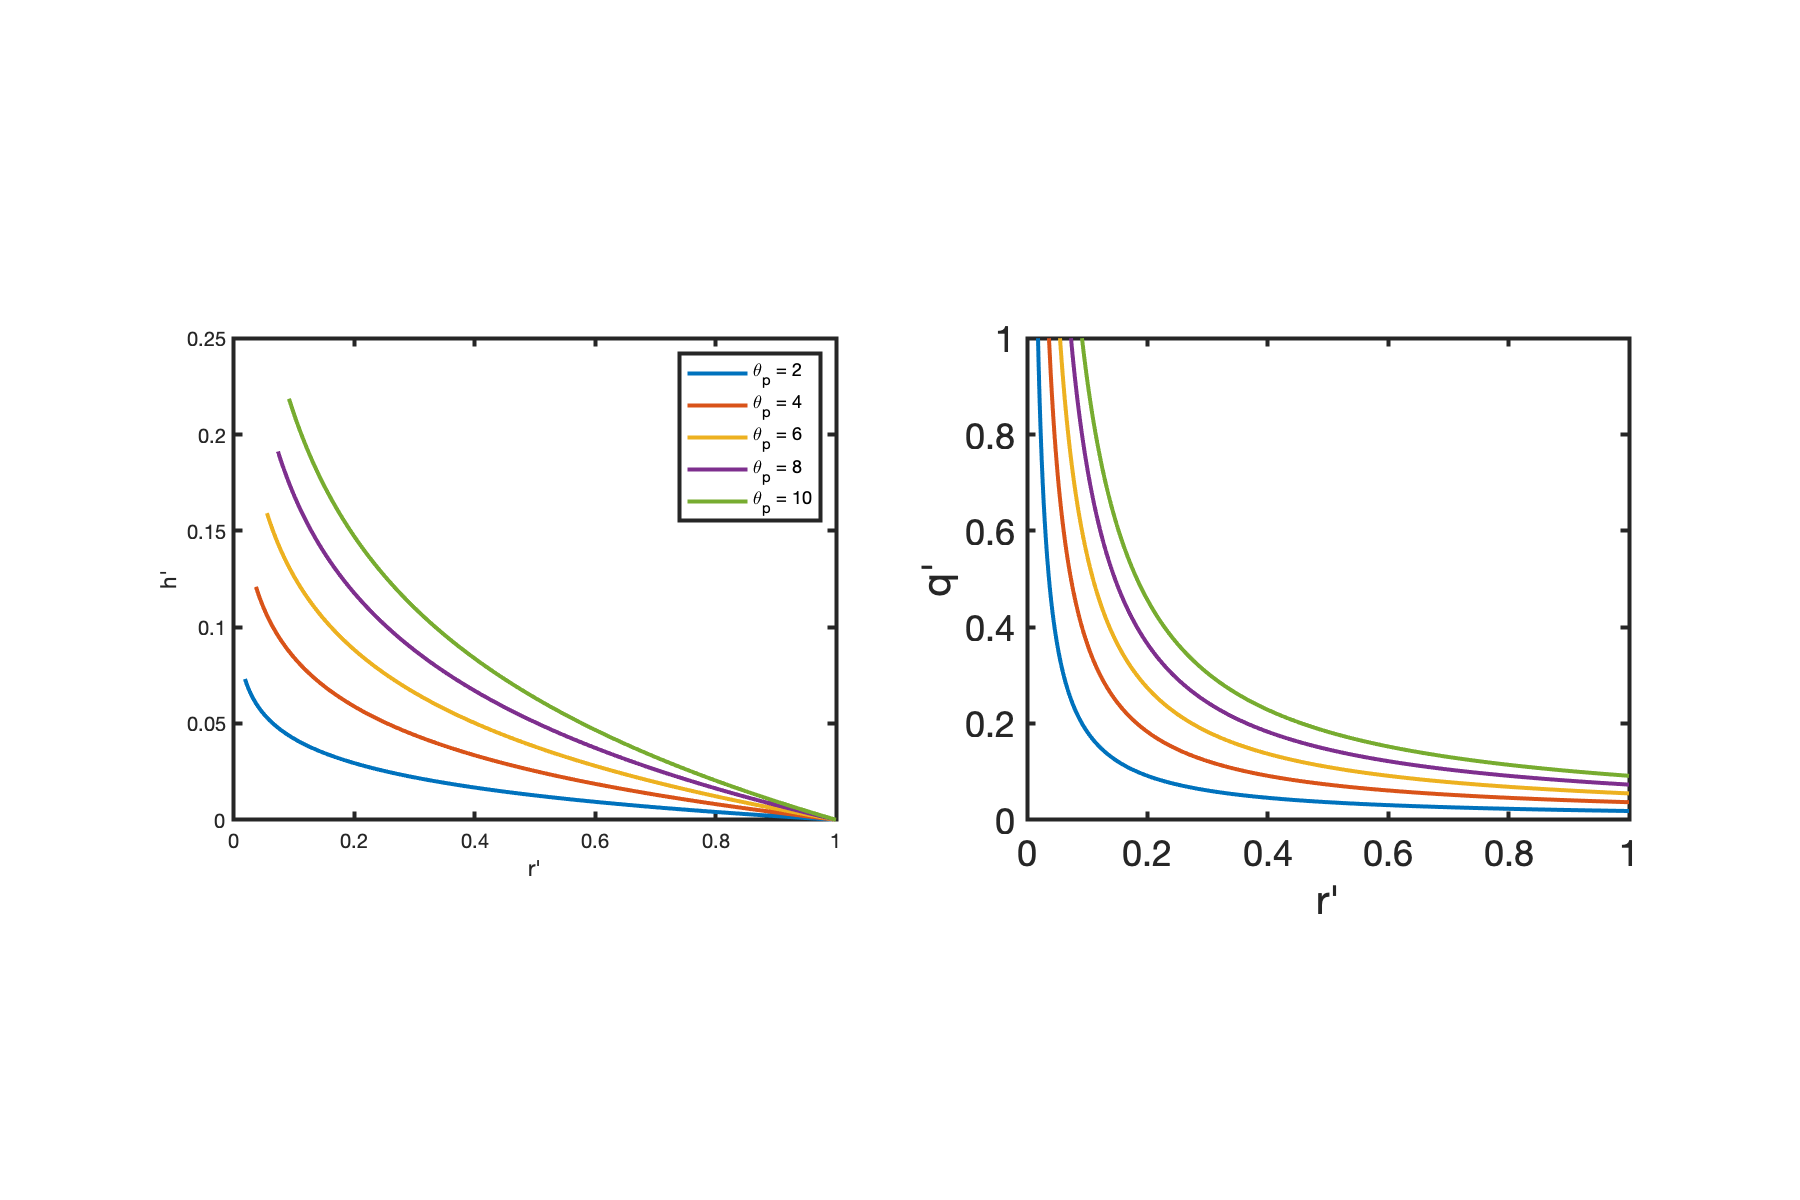

deg_vec = [2:2:10];
figure('position',[10 10 900 600])
for i = 1:length(deg_vec)
    theta_pole = deg2rad(deg_vec(i));
    rp = R_mars*theta_pole;  % [m] distance from pole
    rho = rp/l;
    rD = linspace(rho,1,1e3);
    subplot 121
    plot(rD,hD_ana(rD,rho)),hold on
    subplot 122
    plot(rD,qD_ana(rD,rho)),hold on
end
subplot 121
xlabel 'r''', ylabel 'h''', pbaspect([1 .8 1])
legend('\theta_p = 2','\theta_p = 4','\theta_p = 6','\theta_p = 8','\theta_p = 10')
subplot 122
xlabel 'r''', ylabel 'q''', pbaspect([1 .8 1])

The dimensional solution is obtined substituting the definitions of the dimensional scales to obtain

$h = h_o-\frac{q_i\,r_p}{K}\log\left(\frac{r}{l}\right)$ and $q = q_i \frac{r_p}{r}$.

h_ana = @(r,rp) ho - qi(rp)*rp/K*log(r/l);
q_ana = @(r,rp) qi(rp)*rp./r;

The dimensional solution for the same set of angles of the polar boundary is shown below

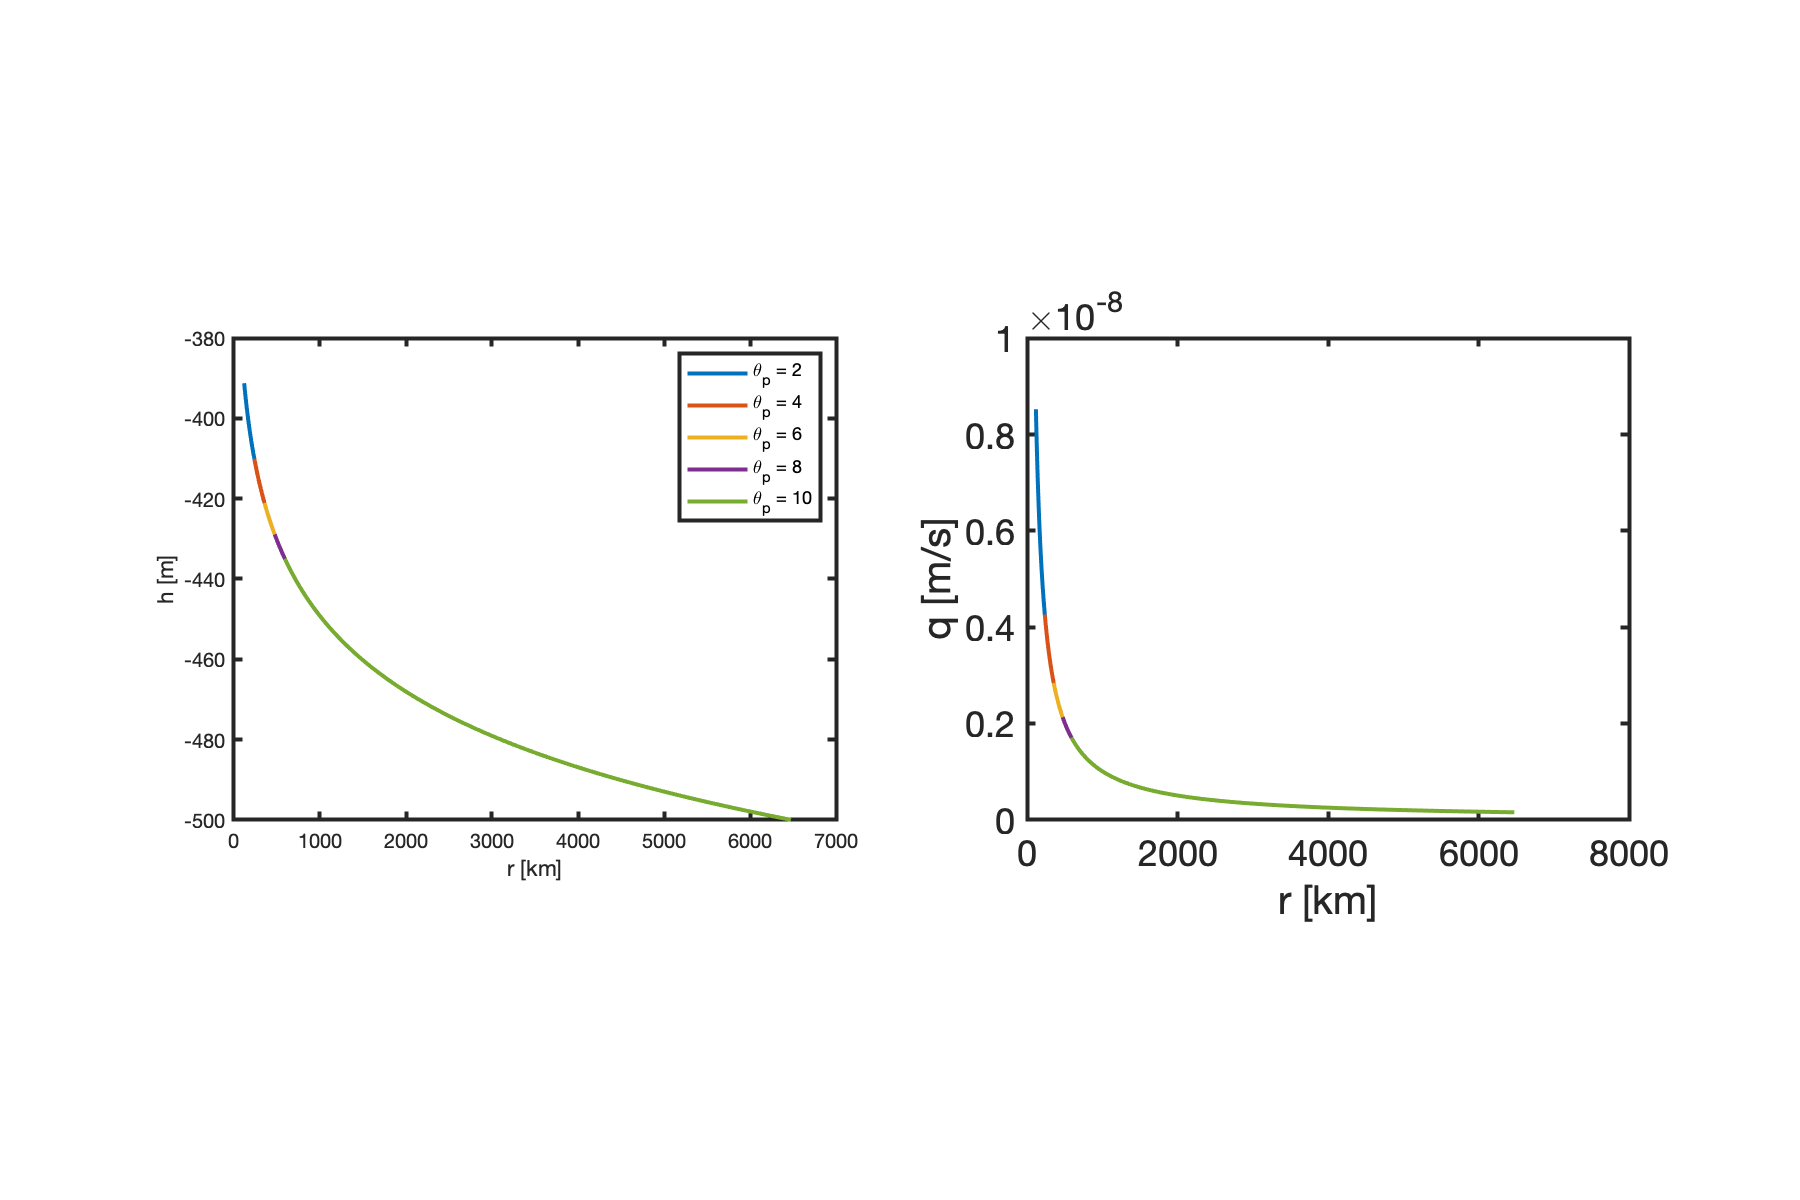

figure('position',[10 10 900 600])
for i = 1:length(deg_vec)
    theta_pole = deg2rad(deg_vec(i));
    rp = R_mars*theta_pole;  % [m] distance from pole
    r = linspace(rp,l,1e3);
    subplot 121
    plot(r/1e3,h_ana(r,rp)),hold on
    subplot 122
    plot(r/1e3,q_ana(r,rp)),hold on
end
subplot 121
xlabel 'r [km]', ylabel 'h [m]', pbaspect([1 .8 1])
legend('\theta_p = 2','\theta_p = 4','\theta_p = 6','\theta_p = 8','\theta_p = 10')
subplot 122
xlabel 'r [km]', ylabel 'q [m/s]', pbaspect([1 .8 1])

Now we can evaluate the effect of the polar reacharge on the heads in the aquifer. Polar reacharge only increases the head by approximately 100 m over its base level, at least for the aquifer permeabilities we have assumed. The value for polar recharge of $Q = 1\,\mathrm{km}^3/\mathrm{yr}$  we have assume of towards the upper end of the range considered by Clifford 1993, which is between 0.01 and 2.2 $\mathrm{km}^3/\mathrm{yr}$.

This shows that the choice of the polar boundary has no influence on the the solution in the domain - as it should be. Of course, this is exactly the example we used to motivae the conservative finite difference method in lecture 3. The flux **q** develops a strong boundary layer as $r_p\rightarrow0$. This would be very difficultto model with methods that do not conserve mass discretely. As such we expect this problem to be solved well by our approach.

## Numerical solution

The construction of the modified divergence will be integrated into the function `build_ops.m` and can be activated by a new field in the `Grid` structure called `Grid.geom = 'cylindrical_r';`.

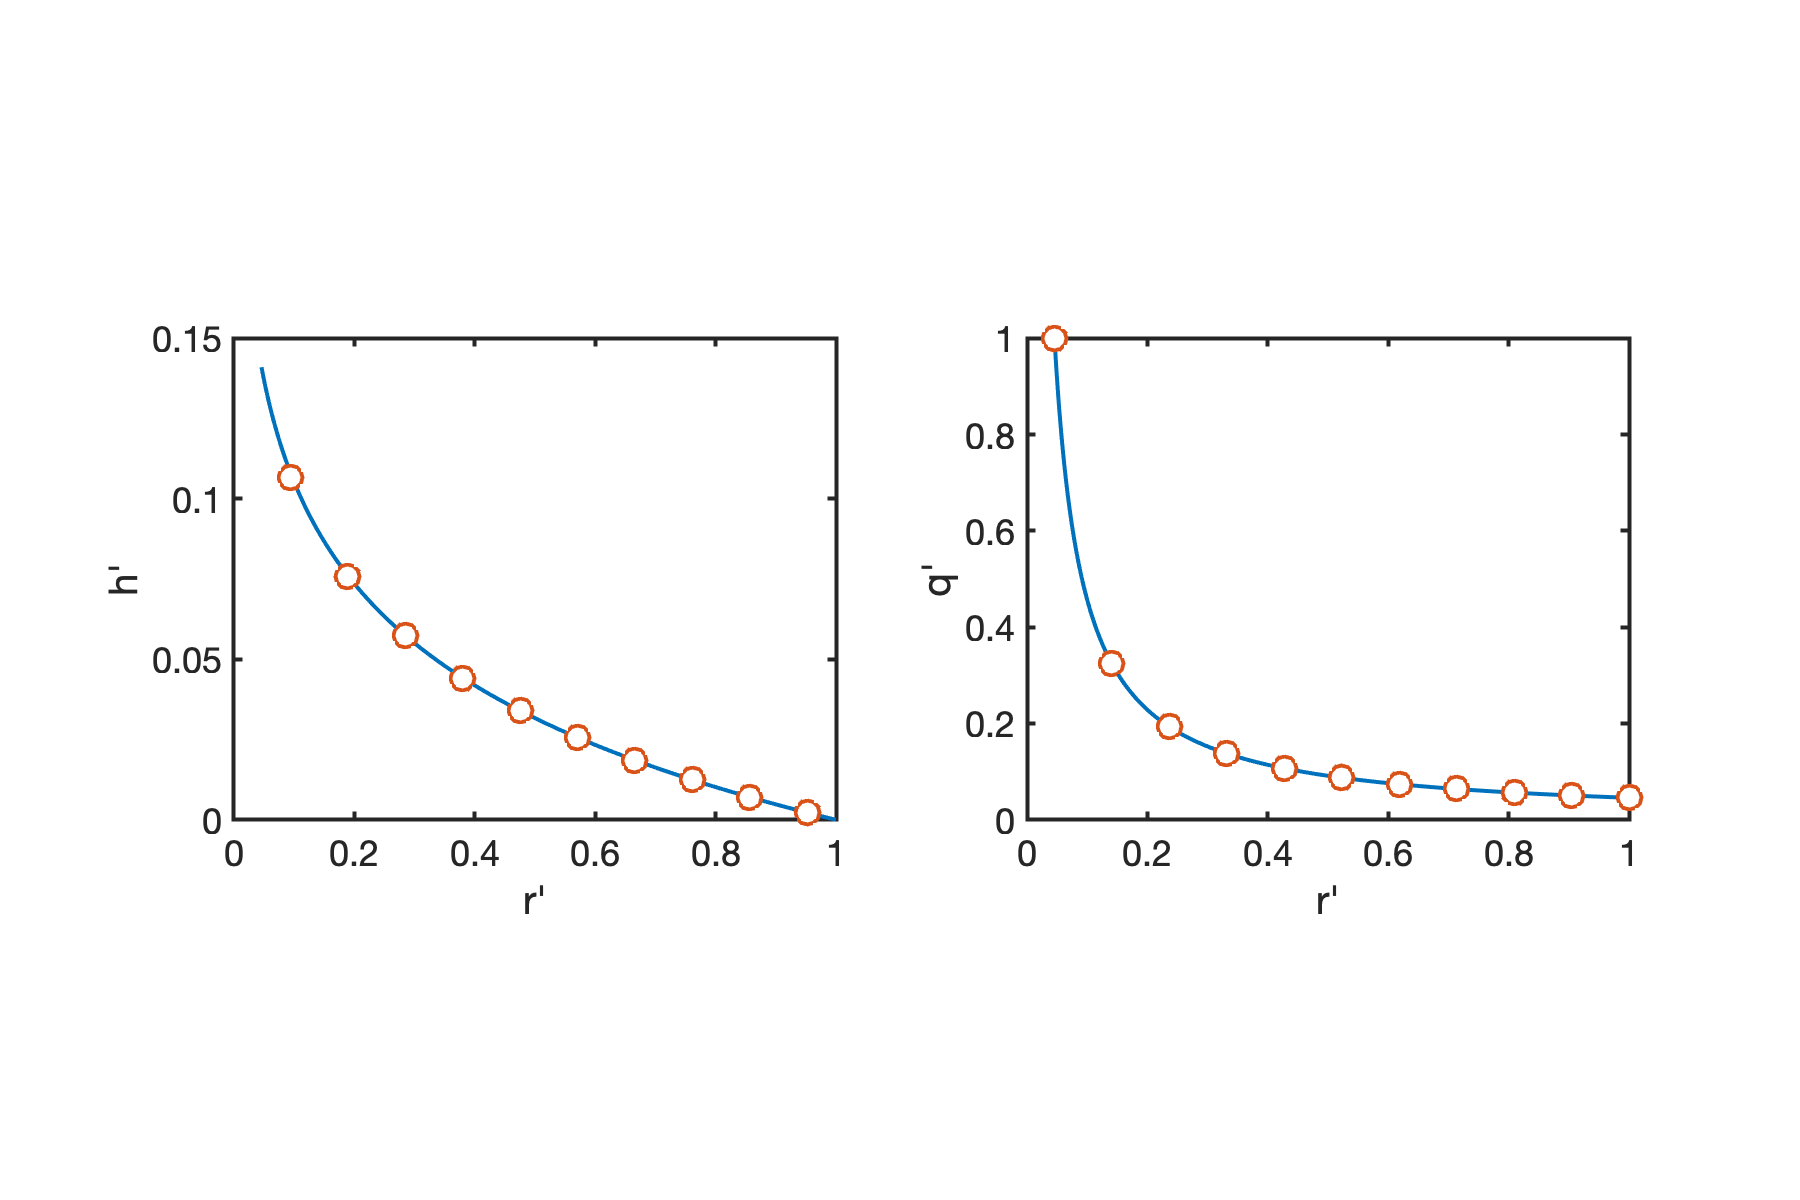

theta_pole = 5;
rp = R_mars*deg2rad(theta_pole);     % [m] distance from pole
rho = rp/l;
Grid.xmin = rho; Grid.xmax = 1; Grid.Nx = 10;
Grid.geom = 'cylindrical_r'; % THIS IS THE NEW PART
[Grid] = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G;
fs = zeros(Grid.N,1);

%% BC's
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = hD_ana(Grid.xc(BC.dof_dir),rho);
BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin;
BC.qb = 1;
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for h and q
hD = solve_lbvp(L,fs+fn,B,BC.g,N);
qD = comp_flux(D,1,G,hD,fs,Grid,BC);

% Plot solution
rD = linspace(rho,1,1e3);
figure('position',[10 10 900 600])
subplot 121
plot(rD,hD_ana(rD,rho),'-',Grid.xc,hD,'o','markerfacecolor','w'),hold on
xlabel 'r''', ylabel 'h''', pbaspect([1 .8 1])

subplot 122
plot(rD,qD_ana(rD,rho),'-',Grid.xf,qD,'o','markerfacecolor','w'),hold on
xlabel 'r''', ylabel 'q''', pbaspect([1 .8 1])

## References

- [Clifford (1993) ﻿A Model for the Hydrologic and Climatic Behavior of Water on Mars, J Geophys. Res. 98(E6), ﻿10973-11016](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1029/93JE00225)

- [Clifford and Parker (2001) The Evolution of the Martian Hydrosphere: Implications for the Fate of a Primordial Ocean and the Current State of the Northern Plains, Icarus, 154(1), 40-79](https://doi.org/10.1006/icar.2001.6671)